clc;
clear;
close all;
addpath(genpath('lib'));
addpath(genpath('data'));

methodname    = {'Observed', 'FCTN-TC'};
Mnum          = length(methodname);
Re_tensor     = cell(Mnum,1);
psnr          = zeros(Mnum,1);
ssim          = zeros(Mnum,1);
time          = zeros(Mnum,1);

## Load initial data

load('HSV_test.mat')
if max(X(:))>1
    X = X/max(X(:));
end

## Sampling with random position

sample_ratio = 0.05;
fprintf('=== The sample ratio is %4.2f ===\n', sample_ratio);

=== The sample ratio is 0.05 ===


T         = X;
Ndim      = ndims(T)

Ndim = 4

Nway      = size(T);
rand('seed',2);
Omega     = find(rand(prod(Nway),1)<sample_ratio)

Omega =      1
    18
    27
    51
   111
   117
   180
   186
   217
   218


F         = zeros(Nway);
F(Omega)  = T(Omega);

i  = 1;
Re_tensor{i} = F;
[psnr(i), ssim(i)] = quality_ybz(T*255, Re_tensor{i}*255);
enList = 1;

## Perform algorithms

i = i+1;
% initialization of the parameters
% Please refer to our paper to set the parameters
opts=[];
opts.max_R = [0,  6,  6,  6;
              0,  0,  6,  6;
              0,  0,  0,  6;
              0,  0,  0,  0];  
opts.R     = [0,  2,  2,  2;
              0,  0,  2,  2;
              0,  0,  0,  2;
              0,  0,  0,  0];
%     R     = [0,  R_{1,2}, R_{1,3}, ..., R_{1,N};
%              0,     0,    R_{2,3}, ..., R_{2,N};
%              ...
%              0,     0,       0,    ..., R_{N-1,N};
%              0,     0,       0,    ...,   0     ];
opts.tol   = 1e-5;
opts.maxit = 1000;
opts.rho   = 0.1;
%%%%%
fprintf('\n');

disp(['performing ',methodname{i}, ' ... ']);

performing FCTN-TC ... 


t0= tic;
% Please see the difference between 'inc_FCTN_TC' and 'inc_FCTN_TC_end' in README.txt. 
%[Re_tensor{i},G,Out]        = inc_FCTN_TC(F,Omega,opts);
[Re_tensor{i},G,Out]        = inc_FCTN_TC_end(F,Omega,opts);

inc_FCTN-TC: iter = 1   RSE = 0.186525   
inc_FCTN-TC: iter = 5   RSE = 0.132066   
inc_FCTN-TC: iter = 10   RSE = 0.073864   
inc_FCTN-TC: iter = 15   RSE = 0.045771   
inc_FCTN-TC: iter = 20   RSE = 0.030701   
inc_FCTN-TC: iter = 25   RSE = 0.021738   
inc_FCTN-TC: iter = 30   RSE = 0.015973   
inc_FCTN-TC: iter = 35   RSE = 0.012044   
inc_FCTN-TC: iter = 40   RSE = 0.010333   
inc_FCTN-TC: iter = 45   RSE = 0.008619   
inc_FCTN-TC: iter = 50   RSE = 0.006727   
inc_FCTN-TC: iter = 55   RSE = 0.005274   
inc_FCTN-TC: iter = 60   RSE = 0.004929   
inc_FCTN-TC: iter = 65   RSE = 0.003859   
inc_FCTN-TC: iter = 70   RSE = 0.003024   
inc_FCTN-TC: iter = 75   RSE = 0.002405   
inc_FCTN-TC: iter = 80   RSE = 0.002246   
inc_FCTN-TC: iter = 85   RSE = 0.001790   
inc_FCTN-TC: iter = 90   RSE = 0.001436   
inc_FCTN-TC: iter = 95   RSE = 0.001671   
inc_FCTN-TC: iter = 100   RSE = 0.001117   
inc_FCTN-TC: iter = 105   RSE = 0.000919   
inc_FCTN-TC: iter = 110   RSE = 0.000759   
inc_FCTN-T

time(i)                     = toc(t0);
[psnr(i), ssim(i)]          = quality_ybz(T*255, Re_tensor{i}*255);
enList = [enList,i];

## Show result

fprintf('\n');

fprintf('================== Result =====================\n');

================== Result =====================


fprintf(' %8.8s    %5.4s    %5.4s    \n','method','PSNR', 'SSIM' );

   method     PSNR     SSIM    


for i = 1:length(enList)
    fprintf(' %8.8s    %5.3f    %5.3f    \n',...
    methodname{enList(i)},psnr(enList(i)), ssim(enList(i)));
end

 Observed    8.416    0.016    
  FCTN-TC    43.912    0.993    


fprintf('================== Result =====================\n');

================== Result =====================


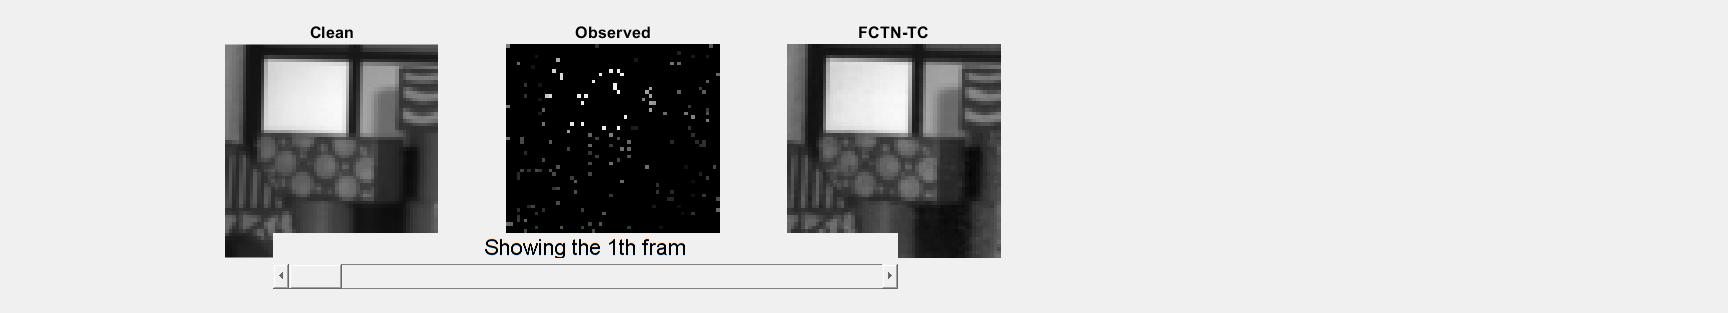

figure,
show_figResult(Re_tensor,T,min(T(:)),max(T(:)),methodname,enList,1,prod(Nway(3:end)))